## 10. Gyakorlat

#### **1. Feladat**

A korábban meghatározott, $f(x)=\sin\left(\frac{\pi}{2} x \right)$ $(x \in [-1,1])$ függvényt interpoláló másodfokú spline-t** írjuk át a globális bázisba!**

*(A részletes megoldás elérhető a gyak_füzet_22_46.pdf 13. oldalán.)*

#### **2. Feladat**

Interpoláljuk az $f(x)=\sin\left(\frac{\pi}{2} x \right)$ $(x \in [-1,1])$ függvényt a $-1,0,1$ alappontokon **globális bázisban (egyoldali hatványfüggvényekkel) **másodfokú spline-nal, $f'(-1)=0$  peremfeltétellel.

A=[1,-1,1,0;1,0,0,0;1,1,1,1;0,1,-2,0]

A =      1    -1     1     0
     1     0     0     0
     1     1     1     1
     0     1    -2     0


b=[-1,0,1,0]'

b =     -1
     0
     1
     0


c=A\b;

A megoldás: $S_2(x)=x^2 + 2x - 2(x-0)_+^2$

Rajzoljuk fel a bázis elemeit!

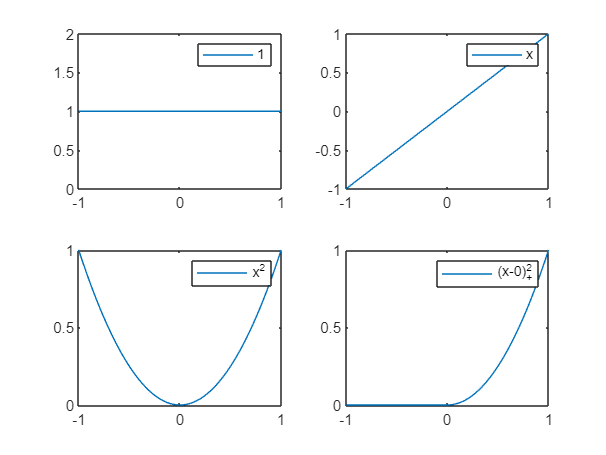

xx=linspace(-1,1,100);
y0=ones(size(xx));
y1=xx;
y2=xx.^2;
y3=max(xx-0,0).^2;

subplot(2,2,1);
plot(xx,y0);
legend('1');
subplot(2,2,2);
plot(xx,y1);
legend('x');
subplot(2,2,3);
plot(xx,y2);
legend('x^2');
subplot(2,2,4);
plot(xx,y3);
legend('(x-0)_+^2')

#### 3. Feladat

Legyen $f(x)=\sin\left(\frac{\pi}{2} x \right)$ $(x \in [0,4])$. Interpoláljuk az $f$ függvényt a $0,~1,~2,~3,~4$ alappontokon harmadfokú spline-nal, periodikus peremfeltétellel globális bázisban (egyoldali hatványfüggvényekkel)!

    a) Készítsük el a LER-t a feladat megoldásához,

    b) majd oldjuk meg azt MATLABbal, végül rajzoljuk fel a spline-t és a függvényt.

*(A részletes megoldás elérhető a gyak_füzet_22_46.pdf 14-15. oldalán.)*

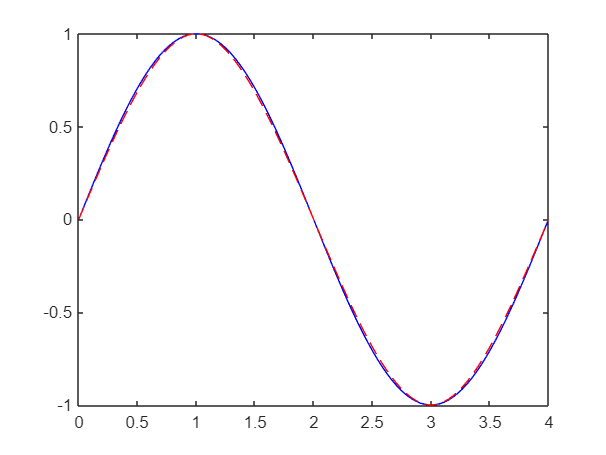

% Megoldás

### **Legkisebb négyzetek módszere**

#### 4. Feladat

Közelítsük a $(-1,1),~(0,2),~(1,2) \in \mathbb{R}^2$ pontokat a négyzetesen legjobban közelítő 

    a) elsőfokú polinommal,

    b) másodfokú polinommal,

    c) harmadfokú polinommal!

Írjuk mindhárom esetben az $Ax=b$ LER-t, majd oldjuk meg a feladatot a Gauss-féle normálegyenletek segítségével! 

*(A megoldás elérhető a gyak_füzet.pdf 19-20. oldalán)*

A MATLAB legkisebb négyzetek módszerét megvalósító függvénye a `polyfit.`

`p=polyfit(x,y,n): `négyzetesen legjobban illeszkedő n-edfokú polinom illesztése: `x` az alappontok, `y` a függvényértékek vektora.

**Emlékeztető**: interpolációs polinomot kapunk, ha `n>=length(x)-1.`

x=[-1,0,1];
y=[1,2,2];
p1=polyfit(x,y,1);
p2=polyfit(x,y,2);
p3=polyfit(x,y,3);

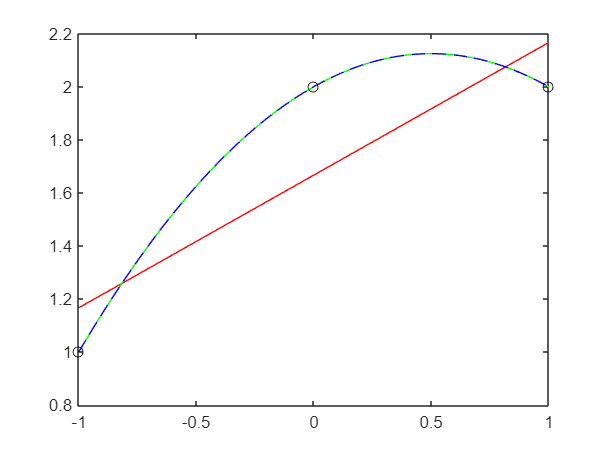


xx=linspace(-1,1,100);
plot(xx, polyval(p1,xx), 'r-');
hold on
plot(xx, polyval(p2,xx), 'g-');
plot(xx, polyval(p3,xx), 'b--');
plot(x,y,'ko');
hold off

#### 5. Feladat

A megadott `x(i), y(i)`  $(i=1,\dots,n)$ pontokra illesszünk elsőfokú polinomot! Számítsuk ki a közelítés hibáját!

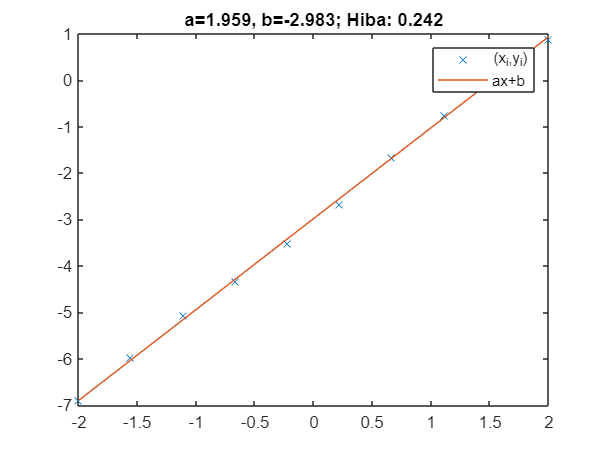

x=linspace(-2,2,10); 
y=2*x-3;
r=0.3;
yh=y+(rand(size(x))-1/2)*r;
p1=polyfit(x,yh,1);
xx=linspace(min(x),max(x),100); 
yy1=polyval(p1,xx);
plot(x,yh,'x',xx,yy1);
hiba1=sqrt(sum((yh-polyval(p1,x)).^2));
% hiba1=norm(yh-polyval(p1,x)).^2)
legend('(x_i,y_i)', 'ax+b')
title(sprintf('a=%.3f, b=%.3f; Hiba: %.3f',p1(1),p1(2),hiba1))

#### 6. Feladat

A megadott `x(i), y(i)`  $(i=1,\dots,n)$ pontokra illesszünk $C e^{ax} = e^{ax+b}$ alakú exponenciáli függvényt!

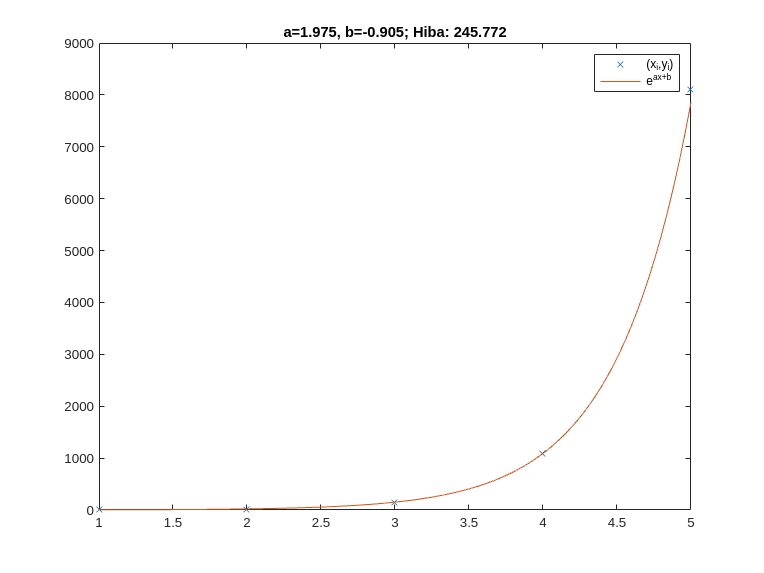

x=1:5; 
y=exp(2*x-1);
r=3.1;
yh=y+(rand(size(x))-1/2)*r;

trf=log(yh);
p=polyfit(x,trf,1);
xx=linspace(min(x),max(x),100); 
yy=polyval(p,xx); 
trff=exp(yy);
plot(x,yh,'x',xx,trff);
hiba1=sqrt(sum((yh-exp(polyval(p,x))).^2));
legend('(x_i,y_i)', 'e^{ax+b}')
title(sprintf('a=%.3f, b=%.3f; Hiba: %.3f',p(1),p(2),hiba1))